# **无线输电系统中互感器的科学计算**

**        无线输电系统是指不经过电缆将电能从发电装置传送到接收端的技术。作为一种特殊的输电方式，它是利用无线电传输电力能量。如下图所示，这种输电系统需要输入端口和接收端口进行交—直流转换，无线输电的部件是通过线圈1和线圈2的互感来完成的。其中，原副线圈间的互感系数可由下述两种方法近似计算：**

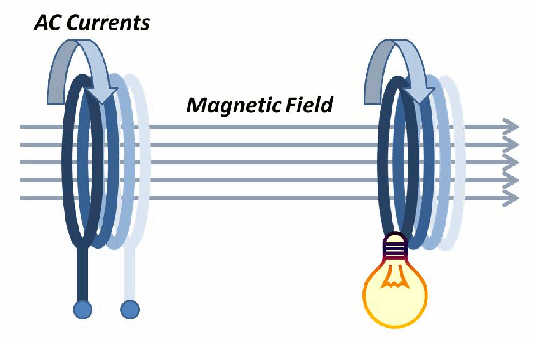

**        设两个相互平行且共轴的圆线圈，其半径分别为a和b，中心间距为d。**

a=0.1;                                          %线圈1半径
b=linspace(0.01*a,a,1000);                   	%线圈2半径
d=5*a;                                       	%二者间距
mu0=4*pi*1e-7;                               	%真空磁导率
theta=atan(b/d);                               	%张角theta
r=sqrt(b.^2+d^2);                             	%r
tmp=r.^2+a^2+2*a*r.*sin(theta);                 %中间变量
k2=4*a*r.*sin(theta)./tmp;                      %k平方
M=2*mu0*a*b./sqrt(tmp).*(2./k2.*(ellipticK(k2)-ellipticE(k2))-ellipticK(k2));   
M=M*1e9;                                  	    %转换单位为nH            
plot(b/a,M);                                 	%绘制曲线，默认为蓝色线条
hold on

- **方法一：诺埃曼公式推演法：**

**             由诺埃曼公式，两线圈之间的互感为：**


$$M{=\frac{\mu_0 }{4\pi }\oint_{l_1 }^{\;} \oint_{l_2 }^{\;} \frac{d\vec{l_1 } \cdot d\vec{l_2 } }{R}=\;\frac{\mu_0 }{4\pi }\int_0^{2\pi } \int_0^{2\pi } \frac{\textrm{abcos}\left(\varphi_1 -\varphi_2 \right)d\varphi_1 d\varphi_2 }{\sqrt{\left\lbrack a^2 +b^2 +d^2 -2\textrm{abcos}\left(\varphi_1 -\varphi_2 \right)\right\rbrack }}\;\;\;}_{\;}$$
 

%诺埃曼公式推演法，计算互感   
b=linspace(0.01*a,a,50);   
for lp=1:length(b)
    M=@(phi1,phi2) mu0/(4*pi)*a*b(lp)*cos(phi2-phi1)./(sqrt(a^2+(b(lp))^2+d^2-2*a*b(lp)*cos(phi2-phi1))); %定义函数
    Mind(lp)=integral2(M,0,2*pi,0,2*pi);      	%做数值积分
end
plot(b/a,Mind*1e9,'g*');                      	%绘制曲线，用绿色*表示


- **方法二：近似方法（当a,b远小于d时）：**

**             由磁偶极子矢量势的相关知识，当半径为a的小线圈中通有电流*****I*****时，在远区的矢势为：**


$$\vec{A} {=\frac{\mu_0 }{4\pi }\frac{\pi a^2 I}{R^2 }\sin \theta \;\vec{e_{\varphi } } }_{\;}$$


**             在半径为b的线圈上，**$\vec{A}$**的值近似为常数，故：**


$$\psi_{12} {=\oint_{l_2 }^{\;} \vec{A} \cdot d\vec{l_2 } =A\cdot 2\pi b=\frac{\mu_0 }{4\pi }\frac{\pi a^2 I}{R^2 }\sin \theta^{\prime } \cdot 2\pi b}_{\;}$$


            ** 式中**$\sin \theta^{\prime } =\frac{b}{\sqrt{b^2 +d^2 }}$,**故**：


$$M=\frac{\psi_{12} }{I}=\frac{\mu_0 }{2}\frac{\pi a^2 b^2 }{{\left(b^2 +d^2 \right)}^{\frac{3}{2}} }$$


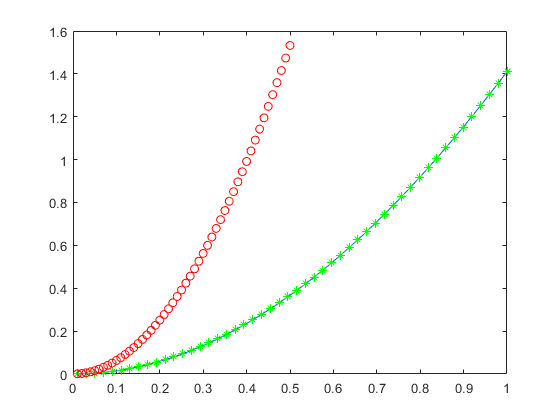

%近似方法，计算互感
b=linspace(0.01*a,0.5*a,50);                    %半径b
M0=mu0*pi*a^2*b.^2/2./(d^2+b.^2).^3/2;         	%近似方法
hold on;                                     	%设置绘图模式：可以叠加
plot(b/a,M0*1e9,'ro');                          %绘制结果，并用红色圆圈表示
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **输出结果如上图所示。从中可以看出，诺埃曼公式和解析法得到的结果吻合的非常好。近似法所得结果，在近似条件满足时，与二者也可重合。因此，可以根据实际情况选择合适的方法。**